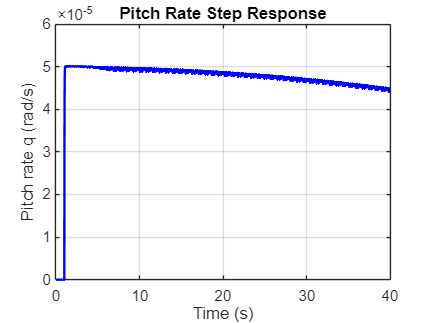

clear
clc


% 0 Controller value

Kp_1 = -99.9;

% 1 Run model
out = sim('Pitch_Rate_Damper.slx');

% 2 Extract time and signal data
t = out.q.Time;      % Time vector
q = out.q.Data;      % Pitch rate (rad/s)

% 3 Compute step response characteristics

% Plot for verification
figure;
plot(t, q, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Pitch rate q (rad/s)');
title('Pitch Rate Step Response');
grid on;


% Compute step response characteristics
info = stepinfo(q, t);
disp('Step Response Characteristics:');

Step Response Characteristics:


disp(info);

         RiseTime: 0.0247
    TransientTime: 39.8388
     SettlingTime: 39.8388
      SettlingMin: 4.1768e-05
      SettlingMax: 5.0109e-05
        Overshoot: 11.1967
       Undershoot: 0
             Peak: 5.0109e-05
         PeakTime: 1.1679

